# Entrega Final

## **Entrega 1. Gráfica de líneas de campo magnético (2D) para un dipolo magnético.**

Declarando constantes y el espacio

% Primera entrega
close all;
%Definiendo Variables constantes
N = 1000; %Número de elementos de corriente
I = 100; %Intensidad de corriente eléctrica (Amperios)
miu = (4*pi) * 10^-7; %Constante de permeabilidad magnética
radio = 1; %radio del aro

%Definiendo el espacio del campo 
spacex = linspace(-3, 3, 15);
spacey = linspace(-3, 3, 15);
spacez = linspace(-3, 3, 15);
[X,Y,Z] = meshgrid(spacex,spacey,spacez);
d_theta = (2*pi)/N;
theta = 0:d_theta:((2*pi));
Bx_total = zeros(length(spacex), length(spacey), length(spacez));
By_total = zeros(length(spacex), length(spacey), length(spacez));
Bz_total = zeros(length(spacex), length(spacey), length(spacez));
R = sqrt(((X).^2+(Y).^2+(Z).^2));
cte=(miu*I)/(4*pi);

Ciclo for para encontrar el campo en cada punto del espacio definido

for i = 1:length(theta) %ciclo for que vaya por cada elemento de corriente en el aro
    radio_dy = radio*sin(theta(i)); %vector en x del radio X.*theta(i)
    radio_dx = radio*cos(theta(i)); %vector en y del radio
    rx=-d_theta*radio_dy;
    ry=d_theta*radio_dx;
    ri_x = X - radio_dx; %vector del punto en el espacio menos el vector del radio en x
    ri_y = Y - radio_dy; %vector del punto en el espacio menos el vector del radio en y
    ri_z = Z; %vector del punto en el espacio menos el vector del radio en z
    ri = sqrt((ri_x.^2)+(ri_y.^2)+(ri_z.^2)); %magnitud de los vectores anteriores
    Bx= (cte *((ry.*ri_z))./(ri.^3)); %se obtiene cada campo en x,y y z
    By= -(cte *((rx.*ri_z))./(ri.^3));
    Bz= (cte*(((rx.*ri_y) - (ry.*ri_x)))./(ri.^3));
    Bx_total = Bx_total + Bx; %se actualia las variables para ser sumadas en cada ciclo
    By_total = By_total + By;
    Bz_total = Bz_total + Bz;
end

Graficando el aro y su campo en 3D

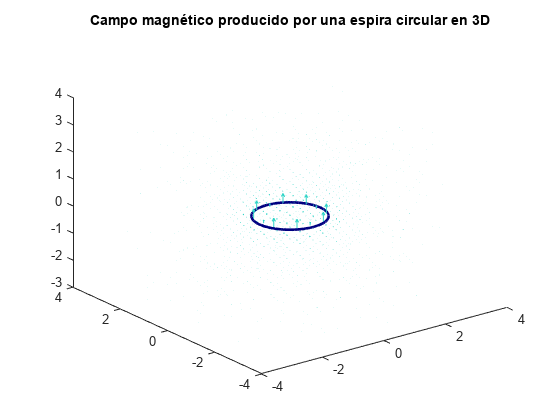

%Graficamos el aro
x = radio * cos(theta);
y = radio * sin(theta);
z = zeros(size(theta));
% Graficar la circunferencia en 3D
figure(1);
plot3(x, y, z, 'b', 'LineWidth', 2, Color = "#000080");
hold on 
%se gráfican los campos
quiver3(X,Y,Z, Bx_total, By_total, Bz_total,"filled",Color =  "#30D5C8");
title("Campo magnético producido por una espira circular en 3D",'FontSize',11)
hold off

Graficando el aro y su campo en 2D

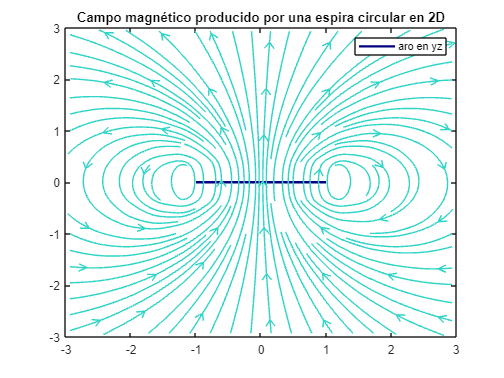

figure(2);
i= [-radio radio];
j = [0 0];
col =[204, 41, 54]/255;
lx = length(spacex);
origen = round((lx/2));
By1 = squeeze(By_total(:,origen,:));
Bz1 = squeeze(Bz_total(:,origen,:));
plot(i,j,'Color', col,'LineWidth',2,Color ="#000080");
a = streamslice(spacex,spacez,By1',Bz1');
set(a,Color =  "#30D5C8");
legend("aro en yz")
title("Campo magnético producido por una espira circular en 2D",'FontSize',11)
hold off

## Entrega 2. Gráfica de líneas de campo magnético (2D) para un dipolo magnético.

Declarando constantes y espacio

%Definiendo Variables constantes
N = 1000; %Número de elementos de corriente
I = 100; %Intensidad de corriente eléctrica (Amperios)
miu = (4*pi) * 10^-7; %Constante de permeabilidad magnética
radio = 1; %radio del aro
num = 5; %numero de aros
d = 0.5; %distancia entre aros
meshgrid_size=5; %valor que puede ser modificado por el usuario, 
%debe de estar de acuerdo a la distancia que recorren las espiras

%Definiendo el espacio del campo 
spacex = linspace(-meshgrid_size, meshgrid_size, 30);
spacey = linspace(-meshgrid_size,meshgrid_size, 30);
spacez = linspace(-meshgrid_size, meshgrid_size,30);
[X,Y,Z] = meshgrid(spacex,spacey,spacez);
d_theta = (2*pi)/N;
theta = 0:d_theta:((2*pi));
Bx_total = zeros(length(spacex), length(spacey), length(spacez));
By_total = zeros(length(spacex), length(spacey), length(spacez));
Bz_total = zeros(length(spacex), length(spacey), length(spacez));
R = sqrt(((X).^2+(Y).^2+(Z).^2));
cte=(miu*I)/(4*pi);
%crear vector de posición en z de los aros
aros = linspace(-((num-1)*d)/2, ((num-1)*d)/2, num);

Iterando el espacio para obtener el campo

for j = 1:length(aros)
    for i = 1:length(theta) %ciclo for que vaya por cada elemento de corriente en el aro
        radio_dy = radio*sin(theta(i)); %vector en x del radio X.*theta(i)
        radio_dx = radio*cos(theta(i)); %vector en y del radio
        rx=-d_theta*radio_dy;
        ry=d_theta*radio_dx;
        ri_x = X - radio_dx; %vector del punto en el espacio menos el vector del radio en x
        ri_y = Y - radio_dy; %vector del punto en el espacio menos el vector del radio en y
        ri_z = Z - aros(j); %vector del punto en el espacio menos el vector del radio en z
        ri = sqrt((ri_x.^2)+(ri_y.^2)+(ri_z.^2)); %magnitud de los vectores anteriores
        Bx= (cte *((ry.*ri_z))./(ri.^3)); %se obtiene cada campo en x,y y z
        By= -(cte *((rx.*ri_z))./(ri.^3));
        Bz= (cte*(((rx.*ri_y) - (ry.*ri_x)))./(ri.^3));
        Bx_total = Bx_total + Bx; %se actualia las variables para ser sumadas en cada ciclo
        By_total = By_total + By;
        Bz_total = Bz_total + Bz;
    end
end

Graficando en 3D el solenoide y su campo

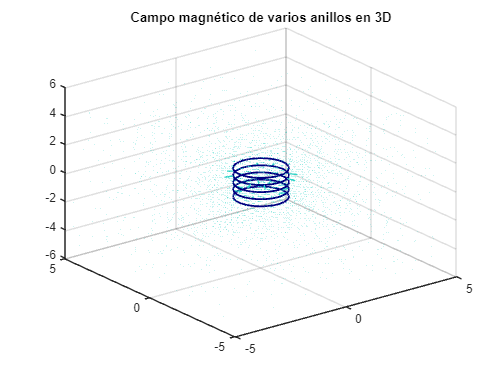

%se gráfican los campos
figure(3);
quiver3(X,Y,Z, Bx_total, By_total, Bz_total,"filled",'b','LineWidth',1,Color =  "#30D5C8")
hold on;

%Graficamos los aros
x = radio * cos(theta);
y = radio * sin(theta);
z = ones(size(theta));
% Graficar las circunferencias en 3D
for j = 1:length(aros)
    z_aros = aros(j) * z; % Vector con la misma longitud que theta y con el valor de aros(j) en cada posición
    plot3(x, y, z_aros, 'b', 'LineWidth', 1.5,Color = "#000080");
    hold on;
end
title("Campo magnético de varios anillos en 3D",'FontSize',11)
hold off

Graficando en 2D el solenoide y su campo

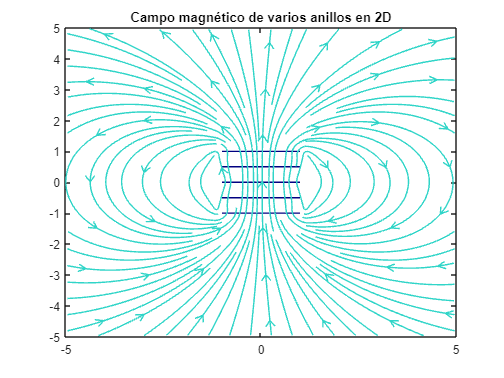

%se grafican los aros en el plano
figure(4);
rad= [-radio radio];
lx = length(spacex);
origen = round((lx/2));
By1 = squeeze(By_total(:,origen,:));
Bz1 = squeeze(Bz_total(:,origen,:));
col =[204, 41, 54]/255;
for k=1:length(aros)
    y = aros(k);
    j =[y y];
    plot(rad,j,Color = "#000080");
    hold on;
end

%se grafica el campo a la mitad del plano x
h = streamslice(spacex,spacez,By1',Bz1');
set(h,Color =  "#30D5C8");
title("Campo magnético de varios anillos en 2D",'FontSize',11)
hold off

## Entrega 3. Simulación del frenado magnético

Inicializando constantes

% Parámetros y condiciones iniciales
mi = 1000;
miu =  (4*pi) * 10^-7;
radio = 10;
I = 1000;
masa = 600;
gravedad = 9.8;

Valores iniciales para empezar las iteraciones con el método de Runge-Kutta

z0 = 329; % Valor inicial de z (altura donde se encontrará el imán)
v0 = 0; % Valor inicial de v
t0 = 0; % Tiempo inicial
tn = 18; % Tiempo final
h = 0.001; % Tamaño del paso

% Funciones del sistema de ecuaciones diferenciales
f1 = @(t, z, v) v;
f2 = @(t, z, v) (3*mi*miu*radio^2*I/(2*masa)) * (z/(radio^2 + z^2)^(5/2)) - gravedad;

% Implementación del método de Runge-Kutta
t_vals = t0:h:tn; % Vector de tiempos
N = length(t_vals); % Número de pasos

z_vals = zeros(1, N); % Vector para almacenar los valores de z
v_vals = zeros(1, N); % Vector para almacenar los valores de v

z_vals(1) = z0; % Valor inicial de z
v_vals(1) = v0; % Valor inicial de v

Empezando el método de Runge Kutta en un ciclo for

% Iteración del método de Runge-Kutta
for i = 1:(N-1)
    t = t_vals(i);
    z = z_vals(i);
    v = v_vals(i);
    
    k1z = h * f1(t, z, v);
    k1v = h * f2(t, z, v);
    k2z = h * f1(t + h/2, z + k1z/2, v + k1v/2);
    k2v = h * f2(t + h/2, z + k1z/2, v + k1v/2);
    k3z = h * f1(t + h/2, z + k2z/2, v + k2v/2);
    k3v = h * f2(t + h/2, z + k2z/2, v + k2v/2);
    k4z = h * f1(t + h, z + k3z, v + k3v);
    k4v = h * f2(t + h, z + k3z, v + k3v);
    
    z_vals(i+1) = z + (k1z + 2*k2z + 2*k3z + k4z) / 6;
    v_vals(i+1) = v + (k1v + 2*k2v + 2*k3v + k4v) / 6;
end

Evaluando la función parámetro de la aceleración con los valores de Z obtenidos con el método de Runge-Kutta

a_vals = [];

for i=1:length(z_vals)
    a_vals(end+1) = (3*mi*miu*radio^2*I/(2*masa)) * (z_vals(i)/(radio^2 + (z_vals(i))^2)^(5/2)) - gravedad;
end

Graficando posición, velocidad y aceleración en contra del tiempo

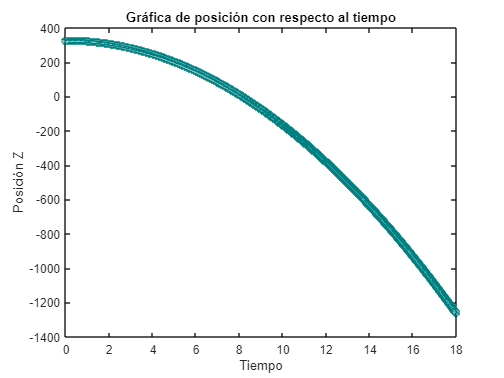

% Graficar la solución
figure(5);
plot(t_vals, z_vals,Color = "#008080", LineStyle="-",Marker="o");
xlabel('Tiempo');
ylabel('Posición Z');
title('Gráfica de posición con respecto al tiempo');
hold off

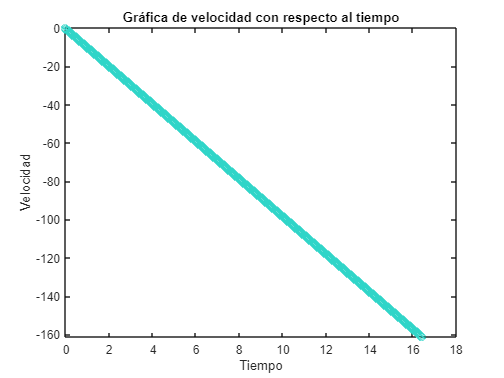

figure(6);
plot(t_vals,v_vals, Color = "#30D5C8",LineStyle="-",Marker="o");
xlabel('Tiempo');
ylabel('Velocidad');
title('Gráfica de velocidad con respecto al tiempo');
hold off

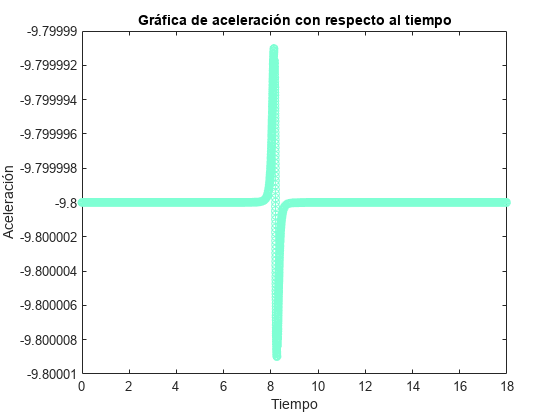

figure(7);
plot(t_vals,a_vals, Color = "#7FFFD4",LineStyle="-",Marker="o");
xlabel('Tiempo');
ylabel('Aceleración');
title('Gráfica de aceleración con respecto al tiempo');
hold off